clear all;
close all;
addpath('E:\MATLAB-atomic-calculation\Plot tools\Colormap');
f1=openfig('\\Artemis-pc\e\Data\2023-09-10\lifetime_left.fig');
ax1=gca;
for j=1:21
    l_num=int16(2*j);

    line=ax1.Children(l_num);

    time(j,:)=line.XData';
    ODsum(j,:)=line.YData'./line.YData(1);
end

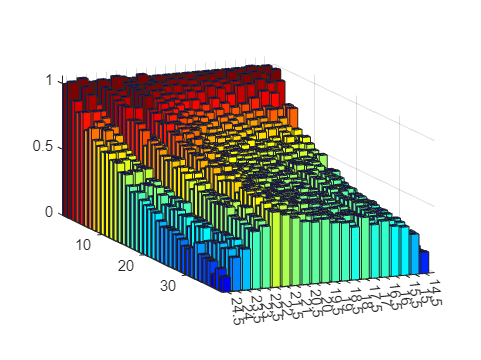


distance=[24.5:-0.5:14.5];
figure;
s1=bar3(ODsum);

for k = 1:length(s1)
    zdata = s1(k).ZData;
    s1(k).CData = zdata;
end
clim([0 1]);

colormap jet;
yticks([1:21])
set(gca,'YTickLabel',flipud(num2str(distance')))


odfinalLeft=ODsum(:,end);


addpath('E:\MATLAB-atomic-calculation\Plot tools\Colormap');
f1=openfig('\\Artemis-pc\e\Data\2023-09-10\lifetime_right.fig');
ax1=gca;
for j=1:21
    l_num=int16(2*j);

    line=ax1.Children(l_num);

    time(j,:)=line.XData';
    ODsum(j,:)=line.YData'./line.YData(1);
end

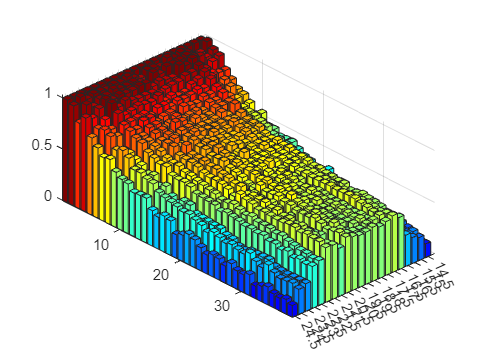


distance=[24.5:-0.5:14.5];
figure;
s1=bar3(ODsum);

for k = 1:length(s1)
    zdata = s1(k).ZData;
    s1(k).CData = zdata;
end
clim([0 1]);

colormap jet;
yticks([1:21])
set(gca,'YTickLabel',flipud(num2str(distance')))

odfinalRight=ODsum(:,end);

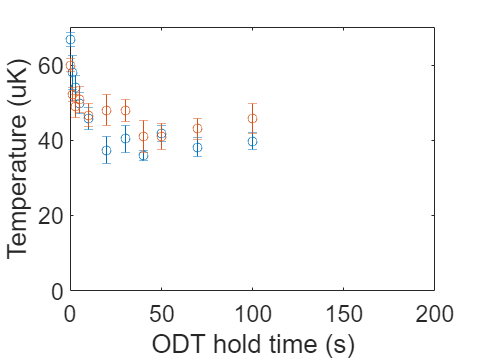

lattice_hold=[0.1,1,3,5,10:10:50,70,100];
H_temp=[66.81,58.08,53.92,49.9,45.75,37.37,40.35,36.08,41.82,38.19,39.81];
H_temp_err=[1.97,4.50,3.24,2.77,2.91,3.60,3.55,1.33,2.16,2.55,2.27];
V_temp=[59.9,52.2,49.11,50.84,46.72,47.97,47.86,41.04,40.94,43.05,45.87];
V_temp_err=[1.73,1.75,3.11,3.49,3.0,4.10,2.93,4.24,3.43,2.83,3.95];
figure
errorbar(lattice_hold,H_temp,H_temp_err,'o')
hold on
errorbar(lattice_hold,V_temp,V_temp_err,'o')
xlim([0 200])
ylim([0 70])
set(gca,'FontSize',16)
xlabel('ODT hold time (s)')
ylabel('Temperature (uK)')